clear all;
close all;


## System configuration

% type of magnetic field
type = 0;
% simulate IMU noise
sigma_acceleration = 0.05;
% simulate IMU bias
sigma_bias = 10^-4;
% simulate magnetometer noise
sigma_magnetometer = 1e-8;
% simulate magnetomer bias
sigma_const_bias_m = 1e-6;
% spacing of sensors
sensor_spacing = 0.1;
% initial position
init_pos = [0.3, 0, 0];
% velocity 
init_vel = [1, 0, 0];
% sampling interval
fs = 100;
dT = 1 / fs;
% monte carlo simulation
N = 4;
% rng(1);

## illustrate magnetic field

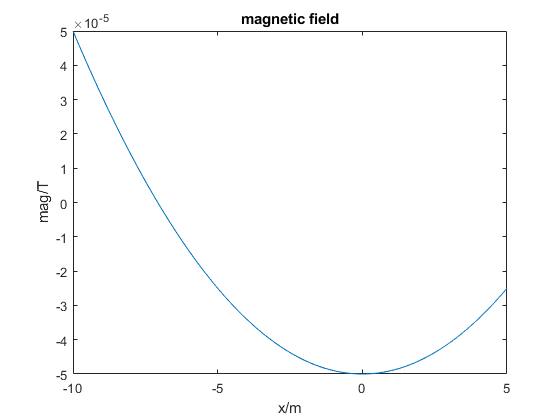

x = -10 : 0.1 : 5;
field1 = arrayfun(@(x) magnetic_model(x, type), x);
figure;
plot(x, field1)
xlabel('x/m');
ylabel('mag/T');
title('magnetic field');

## trajectory

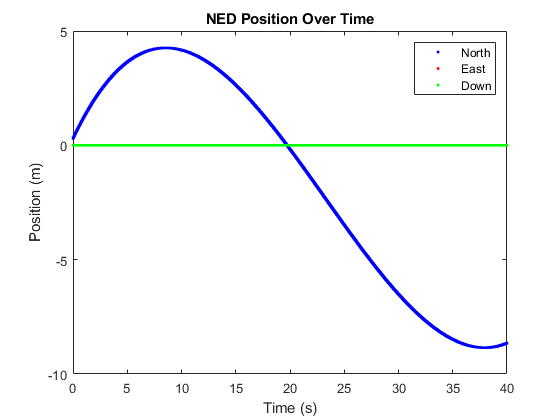

traj = kinematicTrajectory('Position', init_pos, ...
                           'Velocity', init_vel,...
                           'Orientation', quaternion([0 0 0], 'eulerd', 'ZYX', 'frame'));

duration = 40;
numSamples = duration*fs;

% just positive acceleration 

acc = 1 ./ (1 + exp(-((0:numSamples-1)/numSamples - 1/2))) - 0.52;
accBody = [acc.', zeros(numSamples, 2)];

angVelBody = zeros(numSamples,3);


q = ones(numSamples,1,'quaternion');
[pos, orientationNED, vel, accNED, angVelNED] = traj(accBody, angVelBody);

timeVector = 0:1/fs:(duration-1/fs);
figure(3)
plot(timeVector,pos(:,1),'b.',...
     timeVector,pos(:,2),'r.',...
     timeVector,pos(:,3),'g.')
xlabel('Time (s)')
ylabel('Position (m)')
title('NED Position Over Time')
legend('North','East','Down')

## Generate IMU data

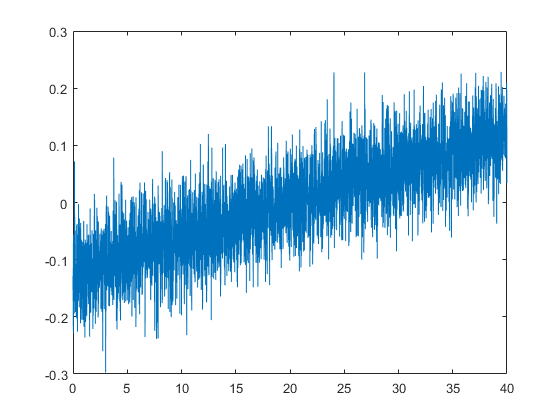


%IMU = imuSensor('SampleRate', fs);
ImuMag_data = repmat(struct('IMU', [], 'MAG', []), N, 1);

% illustruation purpose
accparams = accelparams('RandomWalk', [sigma_bias * sqrt(fs/2) * 0, 0, 0], 'NoiseDensity', sigma_acceleration/sqrt(fs/2), 'ConstantBias', 0.1 * randn(1, 3));
IMU = imuSensor('SampleRate', fs, 'Accelerometer', accparams);
[accelerometerReadings,gyroscopeReadings] = IMU(accBody, angVelBody);
figure;
plot(timeVector, -accelerometerReadings(:, 1));


accBias = zeros(3, N);
for iter = 1 : N
    bias = 0.1 * randn(1, 3);
    accBias(:, iter) = -bias.';
    accparams = accelparams('RandomWalk', [sigma_bias * sqrt(fs/2) * 0, 0, 0], 'NoiseDensity', sigma_acceleration/sqrt(fs/2), 'ConstantBias', bias);
    IMU = imuSensor('SampleRate', fs, 'Accelerometer', accparams);
    [accelerometerReadings,gyroscopeReadings] = IMU(accBody, angVelBody);
    ImuMag_data(iter).IMU = accelerometerReadings;
end

% subplot(1, 2, 1);
% plot(timeVector, accelerometerReadings);

## Generate IMU and Magnetometer data

model = @magnetic_model;
magBias = zeros(3, N);
parfor iter = 1 : N
    magnetometerReadings = zeros(numSamples, 3);
    const_bias = sigma_const_bias_m * rand(1, 3) * 0;
    magBias(:, iter) = const_bias.';
    for i = 1 : size(pos, 1)
        magnetometerReadings(i, 1) = model(pos(i, 1) - sensor_spacing, type) + sigma_magnetometer * randn() + const_bias(1);
        magnetometerReadings(i, 2) = model(pos(i, 1), type) + sigma_magnetometer * randn() + const_bias(2);
        magnetometerReadings(i, 3) = model(pos(i, 1) + sensor_spacing, type) +  sigma_magnetometer * randn() + const_bias(3);
    end
    ImuMag_data(iter).MAG = magnetometerReadings;
end



## EKF Setup

XData = cell(N, 1);
PData = cell(N, 1);



t = now;
d = datetime(t,'ConvertFrom','datenum')

d = datetime
   17-Nov-2021 09:44:27


processNoise = diag([sigma_acceleration^2, 1e-10, 1e-10, sigma_bias^2, 1e-10, 1e-10, 1e-10, 1e-4, 1e-4, 1e-4]);
stateCovariance = diag([0, 0, 0.01,  sigma_const_bias_m^2, sigma_const_bias_m^2, sigma_const_bias_m^2, 1, 1, 1]);


%field1 = arrayfun(@(x) magnetic_model(x), [init_pos(1)-sensor_spacing;init_pos(1); init_pos(1)+sensor_spacing]);
r = sensor_spacing;
H = [r^2 -r 1;0 0 1; r^2 r 1]; 

tic
% run with iteration
for iter = 1 : N
    magnetometerReadings = ImuMag_data(iter).MAG;
    accelerometerReadings = ImuMag_data(iter).IMU;
    
    coeff = H \ (1e6* magnetometerReadings(1, :).');
    %coeff =  H \ (1e6 * field1);
    %p = polyfit([init_pos(1)-sensor_spacing, init_pos(1), init_pos(1)+sensor_spacing], 1e6*magnetometerReadings(1, :), 2);
    initialStateGuess = [init_pos(1); init_vel(1); 0; 0; 0; 0; coeff];
%     obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess, 'HasAdditiveProcessNoise', false, ...
%         'StateTransitionJacobianFcn', @StateTransitionJacobianFcn);
    obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess, 'HasAdditiveProcessNoise', false);
    obj.StateCovariance = stateCovariance;
    
    obj.ProcessNoise = processNoise;
    obj.MeasurementNoise = sigma_magnetometer^2 * eye(3);
    
    X = zeros(numSamples, 9);
    P = zeros(numSamples, 9 , 9);
    X(1, :) = initialStateGuess;
    P(1, :, :) = stateCovariance;
    
    
    % start from the second
    for i = 1 : numSamples - 1
        predict(obj, -accelerometerReadings(i, 1));
        correct(obj, magnetometerReadings(i + 1, :).', sensor_spacing);
        X(i + 1, :) = obj.State.';
        P(i + 1, :, :) = obj.StateCovariance;
    end
    
    XData{iter} = X;
    PData{iter} = P;

end
toc

Elapsed time is 6.983708 seconds.


## Statistics


[absPositionError,stdPositionError, absVelError, stdVelError, mseBiasError, stdBiasError] = calc_error(XData, PData, pos, vel, accBias, numSamples, N);


## Plot error in position/velocity estimation

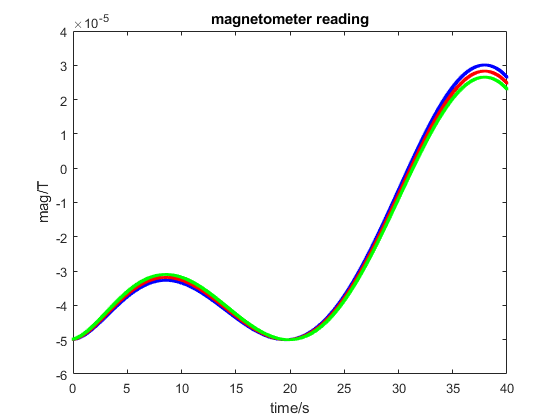

figure;
plot(timeVector,ImuMag_data(1).MAG(:,1),'b.',...
     timeVector,ImuMag_data(1).MAG(:,2),'r.',...
     timeVector,ImuMag_data(1).MAG(:,3),'g.');
xlabel('time/s');
ylabel('mag/T');
title('magnetometer reading');

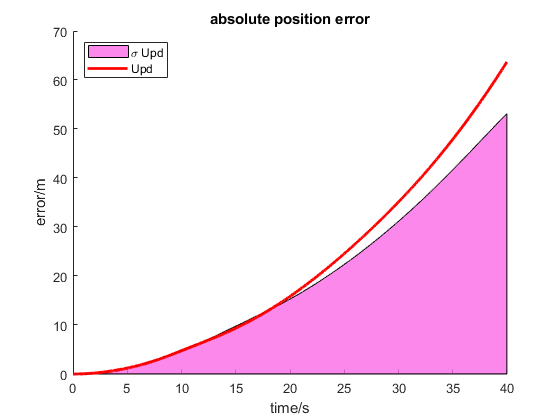


figure;
hold on;

% position error plot
curve1 =  stdPositionError;
curve2 =  zeros(size(absPositionError));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0.9882 0.4157 0.9020], 'DisplayName','\sigma Upd');
h.FaceAlpha = 0.8;
plot(timeVector, absPositionError, 'r','LineWidth', 2, 'DisplayName','Upd');
xlabel('time/s');
ylabel('error/m');
title('absolute position error');
legend('Location','northwest');

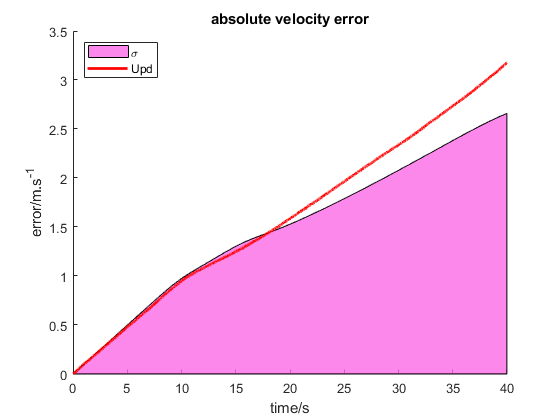


% velocity error plot
figure;
hold on;
curve1 =  stdVelError;
curve2 =  zeros(size(absVelError));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0.9882 0.4157 0.9020], 'DisplayName','\sigma');
h.FaceAlpha = 0.8;
plot(timeVector, absVelError, 'r', 'LineWidth', 2, 'DisplayName','Upd');
xlabel('time/s');
ylabel('error/m.s^{-1}');
title('absolute velocity error');
legend('Location','northwest');

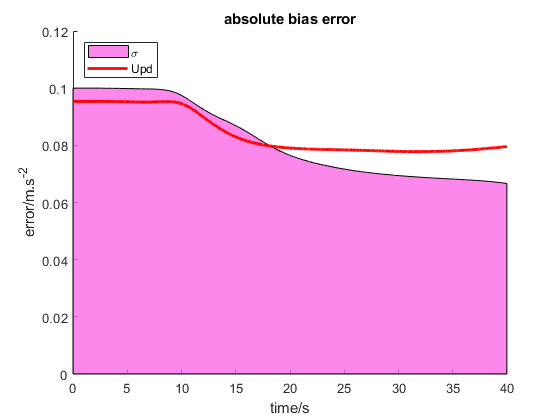


% bias error plot
figure;
hold on;
curve1 =  stdBiasError;
curve2 =  zeros(size(mseBiasError));
inBetween = [curve1; flipud(curve2)];
x = [timeVector fliplr(timeVector)];
h = fill(x, inBetween, [0.9882 0.4157 0.9020], 'DisplayName','\sigma');
h.FaceAlpha = 0.8;
plot(timeVector, mseBiasError    , 'r', 'LineWidth', 2, 'DisplayName','Upd');
xlabel('time/s');
ylabel('error/m.s^{-2}');
title('absolute bias error');
legend('Location','northwest');